%PROGETTO ZERO INTERLEAVING

%
% Lo script deve ricostruire una sequenza x_n a partire da una sua versione "zero interleaved" indicata con y_n
% in cui ogni M campioni sono inseriti M-1 zeri (al posto dei campioni originari)

% Esempio:
% sequenza originaria                       x_n = 1,2,3,4,5,6,7,8,9,10...
% sequenza zero_interleaved (fattore M = 3)  y_n= 1,0,0,4,0,0,7,0,0,10...

% La sequenza di partenza x_n ha 400 campioni ed Ã¨ fornita nel file zerointerleaving.mat

% Si richiede che lo script Matlab esegua le seguenti operazioni:

% - generi la sequeza zero-interleaved y_n con M variabile (M = 2,3,...),
% cioÃ© si deve poter scegliere il numero di campioni (M-1) da azzerare.

% - permetta di scegliere la posizione dei campioni non nulli, es. si chiede la
% possibilitÃ di generare M possibili sequenze con campioni non nulli in posizione
% Mk, Mk+1, Mk+2, ... Mk+(M-1) con k = 0,1,2,...

% - rappresenti graficamente la sequenza x_n e le sequenze y_n (zero_interleaved)
% nel dominio del tempo e delle frequenze (trasformata discreta di Fourier).
%
% - rappresenti graficamente nel dominio del tempo e delle frequenze il filtro impiegato per la ricostruzione
% della sequenza x_n

% - rappresenti graficamente la sequenza originaria x_n e la sua versione
% ricostruita, mostrando che la sequenza ricostruita Ã¨ la stessa qualunque
% sia la scelta della posizione dei campioni non nulli (purchÃ© non vi siano fenomeni di alias).

% - permetta di valutare il massimo valore di M che non produce distorsione del segnale ricostrutito.

% Strutturare lo script Matlab in modo tale che possa essere rapidamente adattato per gestire sequenze in ingresso
% diverse da quella assegnata (es. diverso numero di campioni).
% Definire in modo chiaro le variabili utilizzate e commentare sinteticamente i vari passi dello script.


## **LOAD**

close all;
%clear;
clc;
prompt = ('Inserisci nome file :  ');
nome_file = input (prompt, 's');
load (nome_file);
%load zerointerleaving.mat

## VARIABILI

y = x; %crea un secondo vettore per non modificare sequenza originale
dim = length(x);
M = input('Inserisci M: ');
f_s = 1/M; %frequenza di campionamento, ma potremmo toglierla perché non serve
y_n = zeros(M,dim); %crea una matrice di zeri contenente le M sequenze lungo le righe
Yf_n = y_n; %copia la matrice creata in quella che sarÃ la trasformata
n = (0:dim-1); %intervallo di rappresentazione
Xf=fft(y);
Zf_n=zeros(M,dim);
z=zeros(M,(2*dim)-1);
u=zeros(M,dim);
%definizione asse tempi per filtro
if mod(dim,2)==0
    
    t=-dim/2:dim/2-1;
    
else
    
    t=-floor(dim/2):floor(dim/2);
    
end

## **ZERO-INTERLEAVING**

%ciclo per creare sequenze campionate
for j = 1:M
    
    i = j;
    while i<dim+1
        
        y_n(j,i) = y(i);
        i = i+M;
        
    end
    
end

## **SEQUENZE**

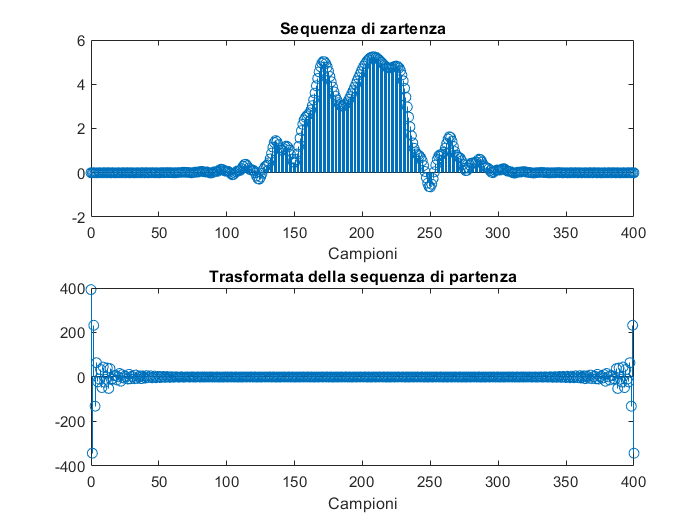


%flag = 0; %flag per molteplici costrutti condizionati
figure
subplot(2,1,1)
stem (n,y);
xlabel ('Campioni')
title('Sequenza di partenza')
subplot(2,1,2)
stem (n,real(Xf));
xlabel ('Campioni')
title('Trasformata della sequenza di partenza')

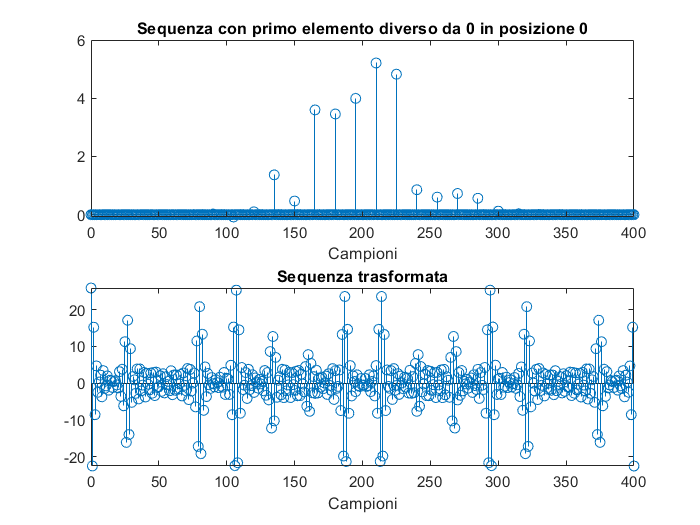

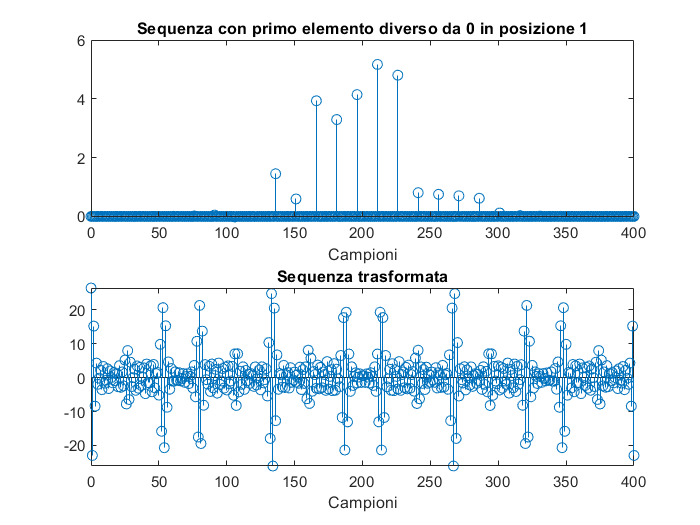

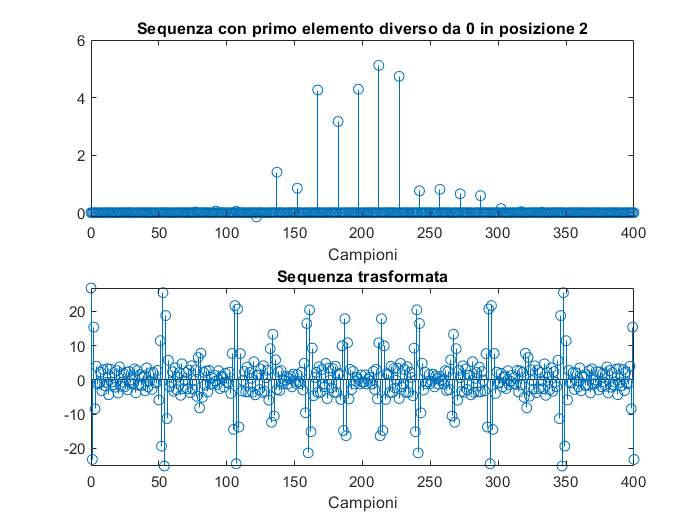

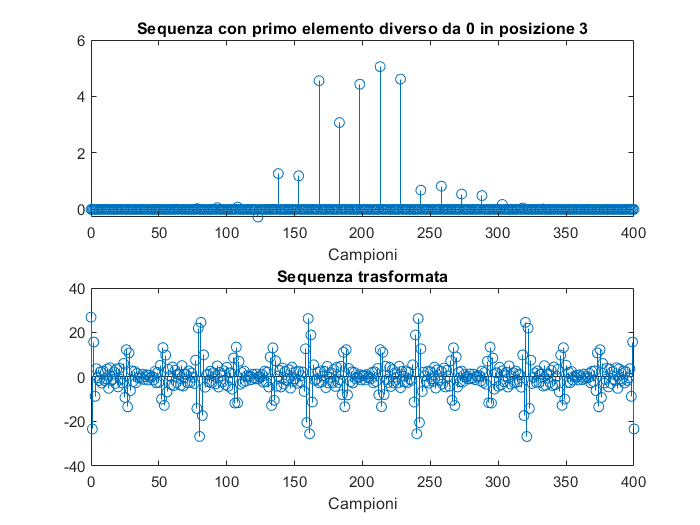

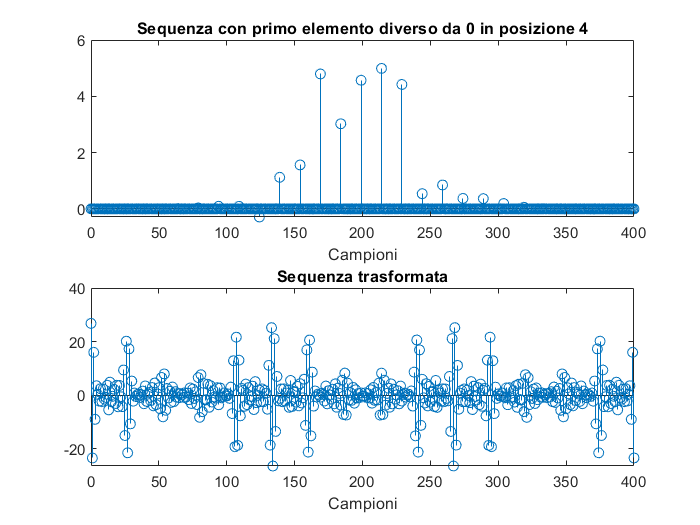

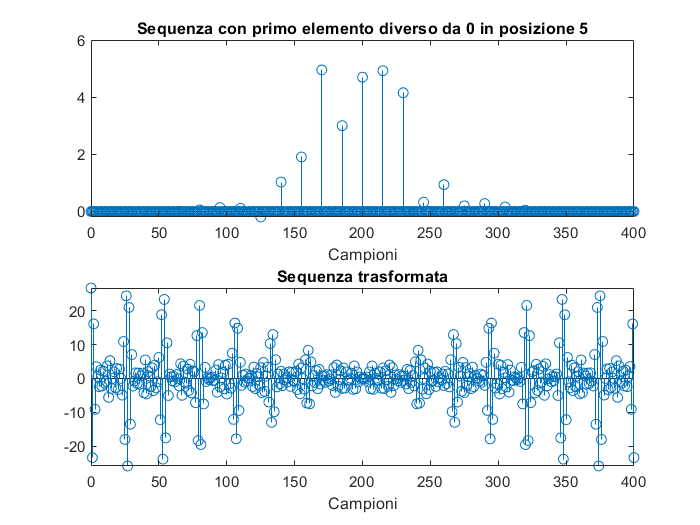

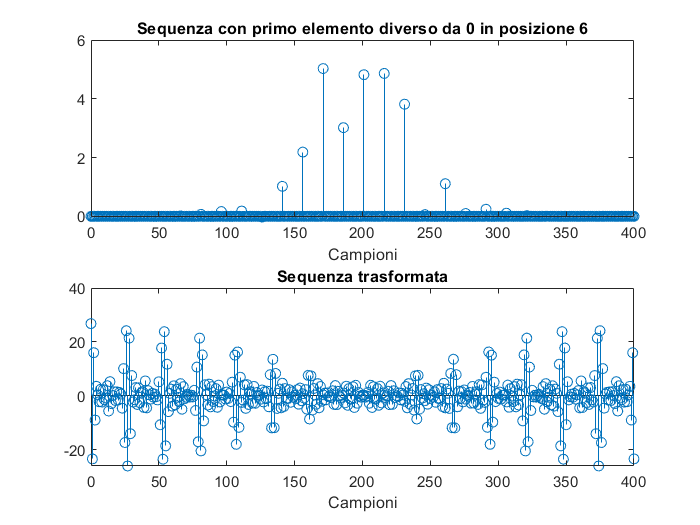

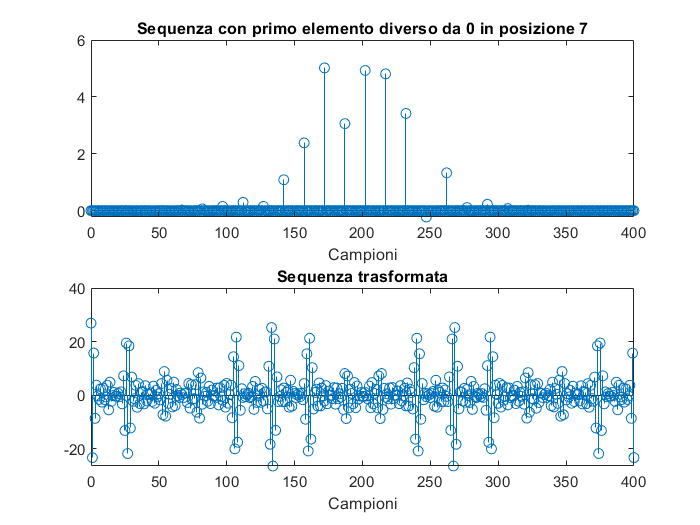

for k = 1:M
        titolo = 'Sequenza con primo elemento diverso da 0 in posizione %d';
        pos = k-1;
        Yf_n(k,:) = fft(y_n(k,:));
        figure
        subplot(2,1,1)
        stem(n,y_n(k,:));
        xlabel ('Campioni')
        title(sprintf(titolo,pos))
        subplot(2,1,2)
        stem(n,real(Yf_n(k,:)));
        xlabel ('Campioni')
        title('Sequenza trasformata')
end

## FILTRO

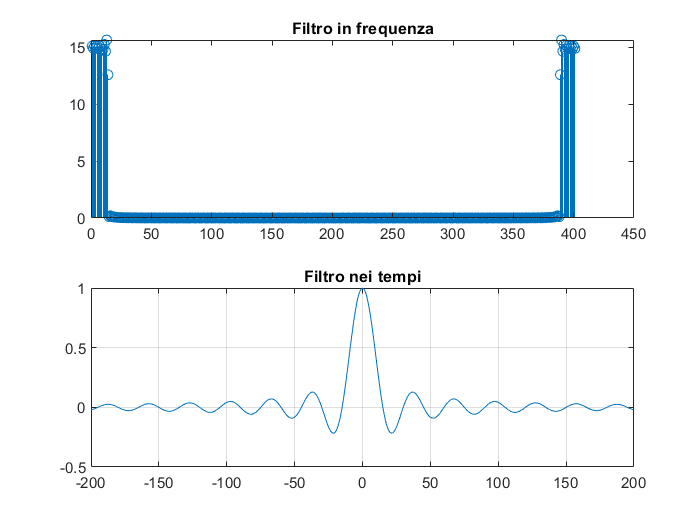

filtro_t=sinc(t/M);
filtro=abs(fft(filtro_t));
figure
subplot (2,1,1)
stem(filtro);
title('Filtro in frequenza')
subplot (2,1,2)
plot(t,filtro_t);
grid on;
title('Filtro nei tempi')

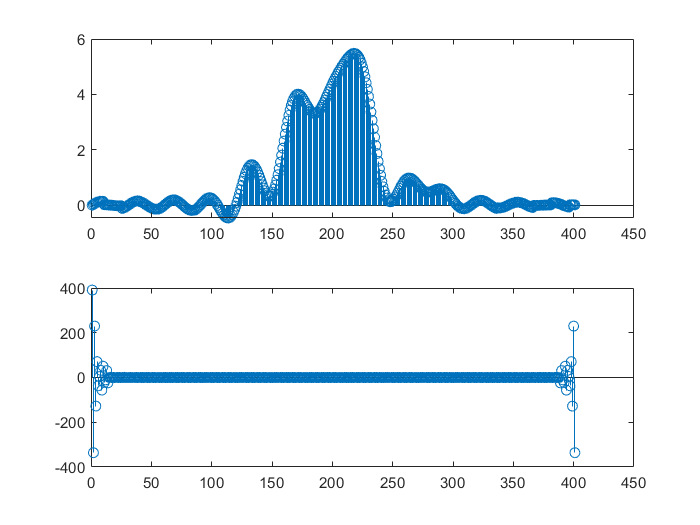

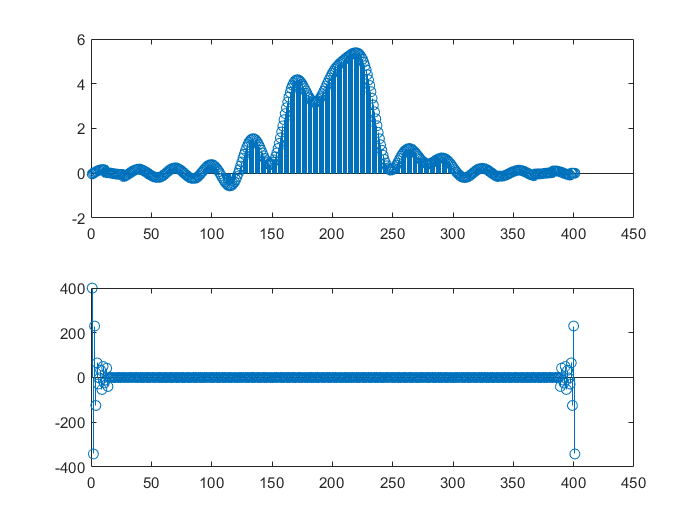

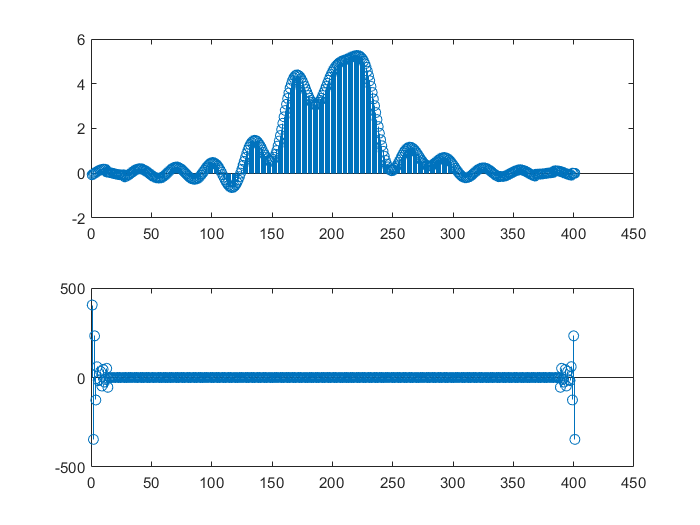

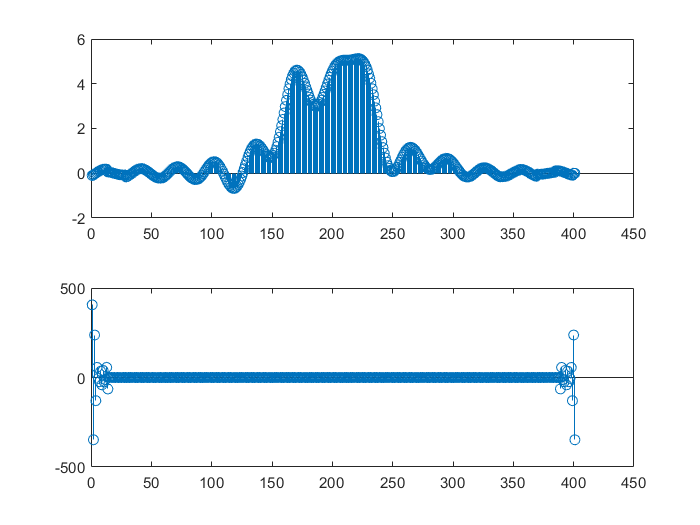

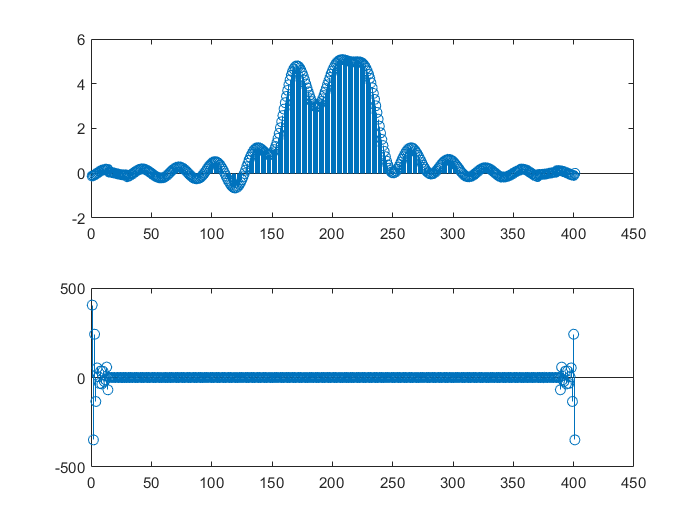

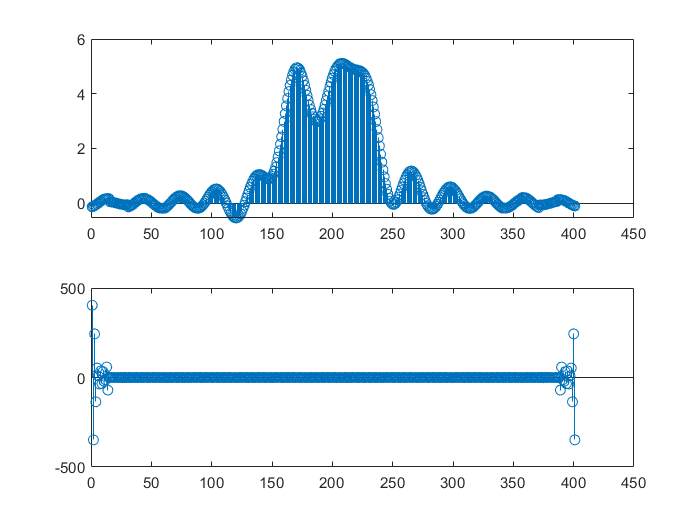

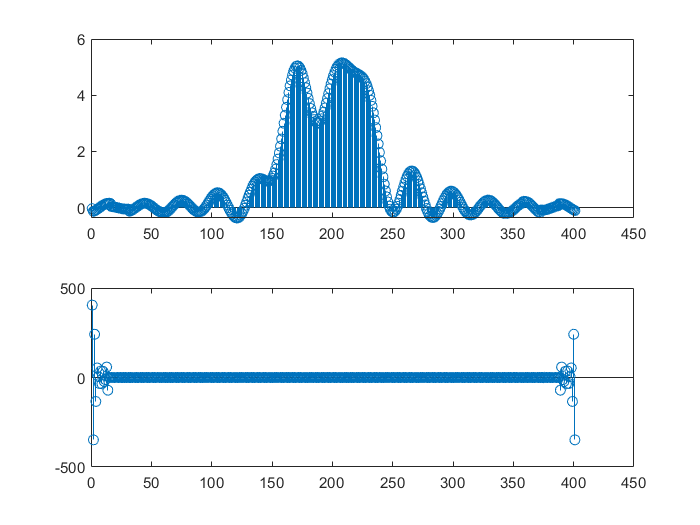

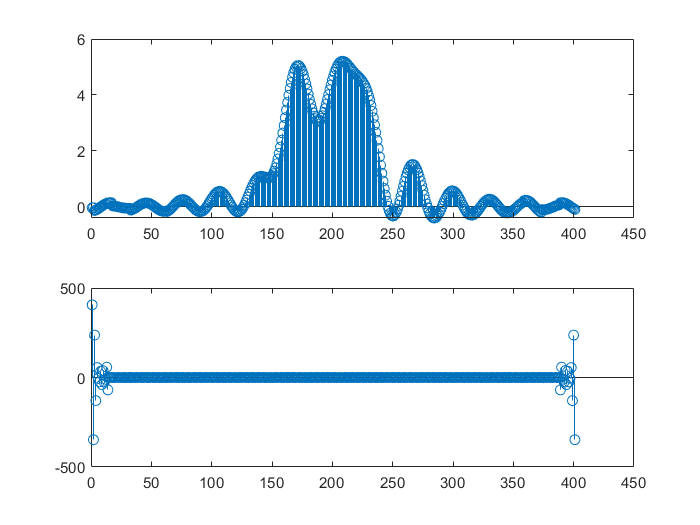

for i=1:M
    
    figure
    Zf_n(i,:)=Yf_n(i,:).*filtro;
    z(i,:) = conv(y_n(i,:),filtro_t);
    u(i,:)=z(i,floor(dim/2)+1:fix((3/2)*dim));
    subplot(2,1,1)
    stem(u(i,:));
    subplot(2,1,2)
    stem(real(Zf_n(i,:)));
    
end

## CALCOLO DELL'ERRORE

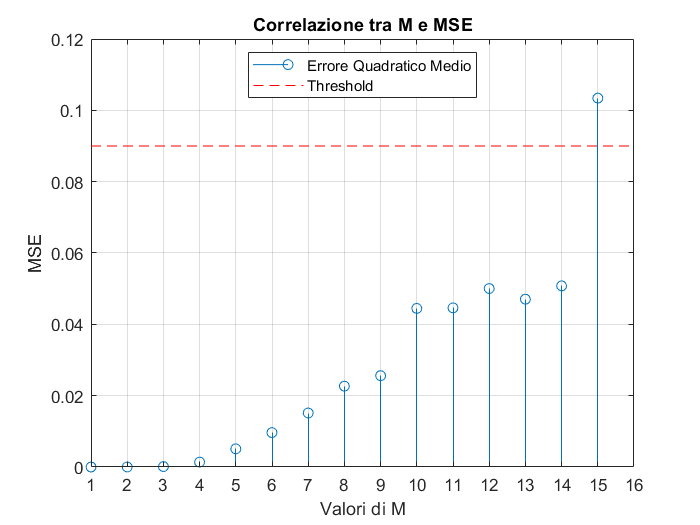

r_n=zeros(dim);
filter_t=zeros(dim);
rec_sign=zeros(M,(2*dim)-1);
sign=zeros(dim);
errorequadratico=zeros(1,dim);
threshold = zeros(1,dim);
%calcolo la matrice contenente tutte le sequenze con primo campione non
%nullo, al variare di M (che va da 1 a dim)
%calcolo la matrice contentente le sequenze ricostruite per ogni riga della
%matrice r_n
for i=1:dim
    
    filter_t(i,:)=sinc(t/i);
    
end

for i=1:dim
    
    l=1;
    while l<dim+1
        r_n(i,l)=y(l);
        l=l+i;
        
    end
    rec_sign(i,:) = conv(r_n(i,:),filter_t(i,:));
    sign(i,:)=rec_sign(i,floor(dim/2)+1:fix((3/2)*dim));
end
%calcolo errore quadratico medio per tutti gli M
for i=1:dim
    
    errorequadratico(i,:)=immse(y,sign(i,:));
    
end
flag=0;

while flag==0
    err=input('inserisci errore quadratico medio massimo accettabile: ');
    i=1;
    while(errorequadratico(i)<err)
        i=i+1;
        
    end
    %i=i-1;%decrementiamo perchÃ¨ se 'i' Ã¨ valore che fa uscire dal ciclo, ultimo valore accettabile Ã¨ 'i-1'
    erroreq=zeros(1,i);%crea vettore di zeri di lunghezza pari alla lunghezza i
    for j=1:i
        
        erroreq(j) = errorequadratico(j);%copia i primi i valori del vettore errorequadratico in erroreq
        threshold (j) = err;
        
    end
    threshold (j+1) = err;
    
    %rappresentazione grafica dell'errore
    figure
    stem(1:i,erroreq,'DisplayName','Errore Quadratico Medio')
    title('Correlazione tra M e MSE')
    xlabel ('Valori di M')
    ylabel ('MSE')
    xticks(1:1:i+1)
    %yticks (0:1e-04:(err+0.2e-03))
    xlim([1 i+1])
    grid on
    hold on
    plot (threshold,'r','LineStyle','--','DisplayName','Threshold')
    legend('Location','North')
    scelta=input('ripetere operazione per errore diverso? s--> si, altri tasti--> no ','s');
    if scelta~='s'
        flag=1;
    end
end

output = '\nIl massimo valore di M tale per cui la distorsione è inferiore al valore richiesto risulta essere %d ';
fprintf(output,i-1)


Il massimo valore di M tale per cui la distorsione è inferiore al valore richiesto risulta essere 14 